## **Объявление условий задачи**

F = @(x,y) -50*(y - cos(x));          %Простой пример жесткой задачи
x_0 = 0;
y_0 = 0;

% F = @(x,y)[ 2*x*(y(2))^(1/2.5)*(y(4));    %Задание из отчета
%  5*x*exp(2.5*(y(3)+3))*(y(4));
%  2*x*(y(4));
%  -2*x*log(y(1))];
% x_0 = 0;
% y_0 = [1 1 -3 1];


Задание величины шага, точности

RightBorder = 2;
h = 0.05;
tol = 10^(-6);

## Вызов функций для решения задачи

[M,K] = ImplicitEuler (F, x_0, y_0, h, RightBorder);

[A,B] = ExplicitRungeKuttaMethod (F, 18, x_0, y_0, 1/10, RightBorder);

[Aa,Bb] = RKC1 (F, 8, 0.05, x_0, y_0, 1/10, RightBorder);

## Построение графиков

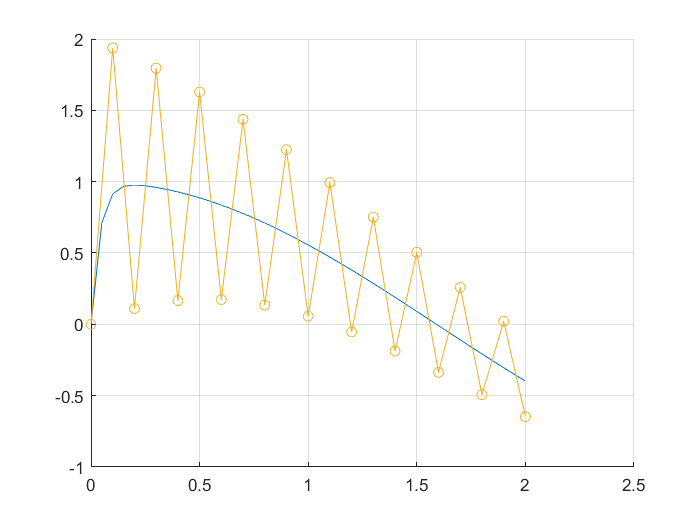

figure
hold on
grid on
plot (M,(K(1,:)));
plot (A,(B(1,:)),'--');
plot (Aa,(Bb(1,:)),'-o');